% 1. LOAD STANDARDIZED DATA (from September Task 5)
% standardized.mat holds trainData, testData, and their labels. 
% Each row is one 5000-sample vibration window.
load("standardized.mat")
YTrain = categorical(trainLabels);
YTest  = categorical(testLabels);

% just checking that there are 3 classes, 131 per class in train, 34 in test
categories(YTrain)

ans = 3×1 cell array
    {'InnerRaceFault'}
    {'Normal'        }
    {'OuterRaceFault'}


summary(YTrain)


YTrain: 393×1 categorical

     InnerRaceFault      131 
     Normal              131 
     OuterRaceFault      131 
     <undefined>           0 


summary(YTest)


YTest: 102×1 categorical

     InnerRaceFault      34 
     Normal              34 
     OuterRaceFault      34 
     <undefined>          0 



% checking September's standardization
mean(trainData(:)), std(trainData(:), 1)

ans = 3.0284e-19

ans = 1

mean(mean(trainData, 1)), mean(std(trainData, 1, 1))

ans = -2.0721e-20

ans = 1

mean(trainData(1:3, :), 2)

ans =    -0.0505
   -0.0548
   -0.0485



% 2. STANDARDIZE THE VALIDATION SET
raw    = load("train.mat");
rawVal = load("val.mat");

% fit the mean and std on the TRAINING data only, one value per column
mu    = mean(raw.trainData, 1);
sigma = std(raw.trainData, 1, 1);

% checking that standaridzation matches trainData
max(abs((raw.trainData - mu) ./ sigma - trainData), [], "all")

ans = 7.1054e-15


% applying the training mean/std to val
valDataStd = (rawVal.valData - mu) ./ sigma;
YVal = categorical(rawVal.valLabels, categories(YTrain));
summary(YVal)


YVal: 27×1 categorical

     InnerRaceFault      9 
     Normal              9 
     OuterRaceFault      9 
     <undefined>         0 



save("scaler.mat", "mu", "sigma");

% 3. RESHAPE DATA (was causing an error and this is recommended way to fix 
XTrain = num2cell(trainData.', 1).';   
XVal   = num2cell(valDataStd.', 1).';
XTest  = num2cell(testData.', 1).';

classNames = categories(YTrain);

size(XTrain{1})

ans =         5000           1


size(XTrain)

ans =    393     1



% define the 1d cnn (baseline)
numClasses = numel(classNames);

layers = [
    sequenceInputLayer(1, MinLength=5000)

    convolution1dLayer(64, 16, Padding="same")
    batchNormalizationLayer
    reluLayer
    maxPooling1dLayer(4, Stride=4)

    convolution1dLayer(32, 32, Padding="same")
    batchNormalizationLayer
    reluLayer
    maxPooling1dLayer(4, Stride=4)

    convolution1dLayer(16, 64, Padding="same")
    batchNormalizationLayer
    reluLayer

    globalAveragePooling1dLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(numClasses)
    softmaxLayer];

%analyzeNetwork(layers)

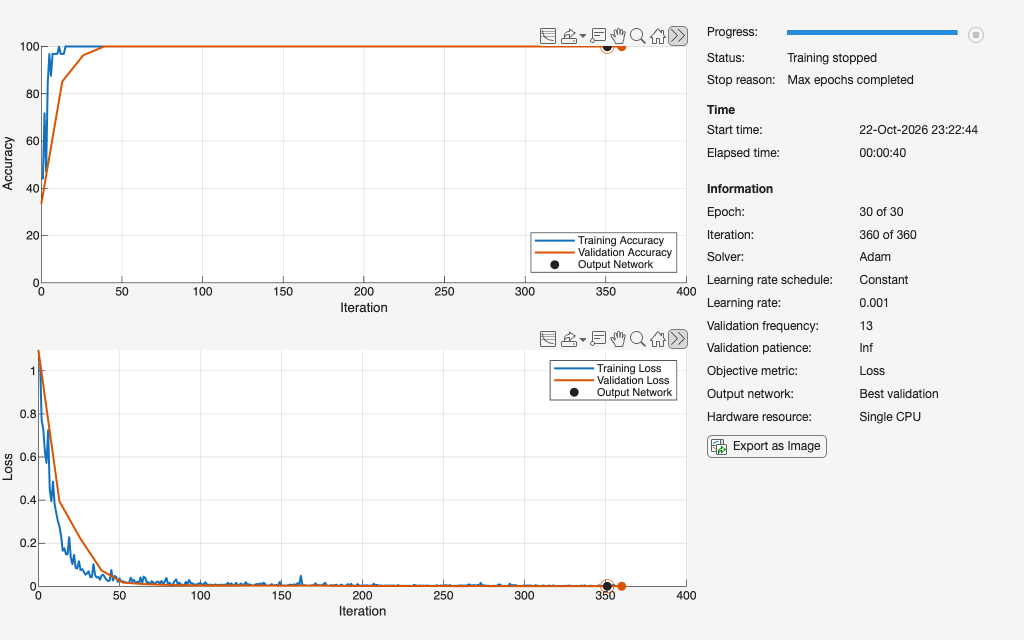

% train
options = trainingOptions("adam", ...
    InitialLearnRate=1e-3, ...
    MaxEpochs=30, ...
    MiniBatchSize=32, ...
    Shuffle="every-epoch", ...
    ValidationData={XVal, YVal}, ...
    ValidationFrequency=13, ...
    Metrics="accuracy", ...
    Plots="training-progress", ...
    Verbose=false);

net = trainnet(XTrain, YTrain, layers, "crossentropy", options);

% way to test
scores  = minibatchpredict(net, XTest);
YPred   = scores2label(scores, classNames);
testAcc = mean(YPred == YTest)

testAcc = 1

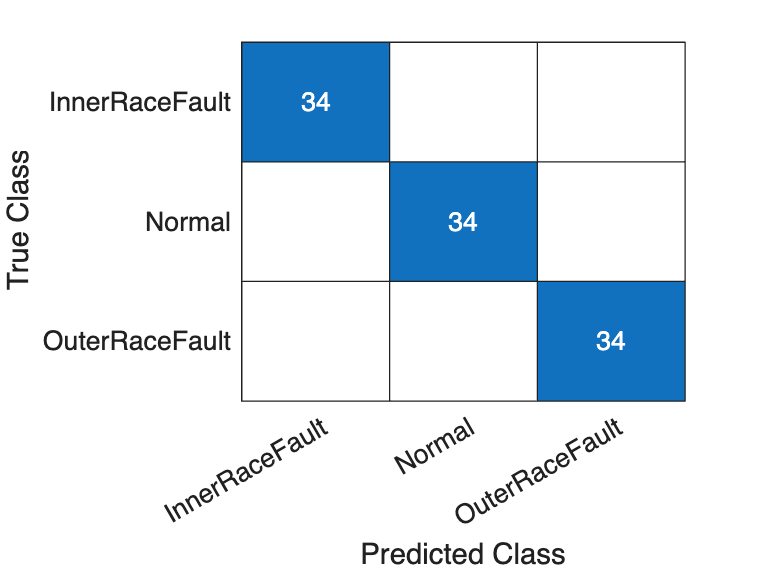


figure; confusionchart(YTest, YPred);


numLearnables = sum(cellfun(@numel, net.Learnables.Value))

numLearnables = 50707


save("baseline_net.mat", "net", "testAcc");
d = dir("baseline_net.mat"); sizeMB = d.bytes / 1e6

sizeMB = 0.1959